Ray tracing using geometrical optics, by Robert Paddock

Design for Oliver 2023 experiment

*This code allows you to test different lens setups by using basic geometric optics. It will calculate the position and magnification of any image planes, and plot the ray traces through the system. This is done by describing rays using position and angle vectors, and describing lenses using standard matrix descriptions for thin lenses. The size of lenses and non-focussing components are included, and the code will use these to determine losses through the system.*

# Simulating the setup

clear all

%Define diameters of each component in 1) the optical relay to the VISAR, 2) the first
%VISAR

%Define diameters of the components in sequence in 1) the relay and 2) the VISAR. These
%will be called later.
LensDiameters = [2 2 2] * 25.4 * 0.9; %3x 2 inch lenses in chamber
LensDiametersVISAR = [1 1 1 1 2] * 25.4 * 0.9; %4x 1 inch lenses inside VISAR, and the 2 inch lens outside


%Define focal length of first lens
FocalLength = 200;
%Generate 1000 rays at random positions and angles on the object. Only rays that
%will be captured by the first lens are generated.
[RayRadii, RayAngles, CaptureAngles] = CaptureLightMC2(0.1, 1000, FocalLength, LensDiameters(1));

%Position defines how far we are along optical path
Position = 0;
%Ray losses will be used to store rays that leave the system.
RayLosses = [zeros(size(RayRadii,1),1)];

%Propogate through the optical system in order that the ray sees them.
%Start with the optical relay up to the beam splitter
%Each function takes the ray radii, ray angle, ray losses, position arrays
%as standard so it can add to them. The free space function propogates the
%ray through a specified distance of free space. The lens array propogates
%them through a lens of given diameter and focal length.
%NonFocussingComponent checks that the ray passes through a component of a
%given diameter (which does not otherwise affect beam propogation). Each
%function updates the four output arrays, allowing the functions to be
%applied in turn.
[RayRadii, RayAngles, RayLosses, Position] = FreeSpace(RayRadii, RayAngles, RayLosses, Position, 200); % Propogates rays through 200mm of free space to first lens
[RayRadii, RayAngles, RayLosses, Position] = Lens(RayRadii, RayAngles, RayLosses, Position, LensDiameters(1), 200); %L1 - Propogates ray through f=200mm lens.
[RayRadii, RayAngles, RayLosses, Position] = FreeSpace(RayRadii, RayAngles, RayLosses, Position, 1000); %Propogates rays though 1000mm of free space
[RayRadii, RayAngles, RayLosses, Position] = Lens(RayRadii, RayAngles, RayLosses, Position, LensDiameters(2), 1000); %L2 - Propogates rays through f=1000mm lens.
[RayRadii, RayAngles, RayLosses, Position] = FreeSpace(RayRadii, RayAngles, RayLosses, Position, 1000); %Free space - and so on...
[RayRadii, RayAngles, RayLosses, Position] = FreeSpace(RayRadii, RayAngles, RayLosses, Position, 300);
[RayRadii, RayAngles, RayLosses, Position] = Lens(RayRadii, RayAngles, RayLosses, Position, LensDiameters(3), 300); %L3

%Could continue as above for this setup. By introducing new variable names,
%you can split the setup at a point (i.e. if a beamsplitter is being used -
%RayRadii contains all information up to this point, and RayRadiiVISAR
%continues it for next set of lenses. If split, RayRadii2 could be used to
%describe the alternative beampath).
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadii, RayAngles, RayLosses, Position, 3000); 
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = Lens(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, LensDiametersVISAR(1), 400); %VISAR lens 1
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 400);
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 250);
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = Lens(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, LensDiametersVISAR(2), 250); %VISAR lens 2
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 1000);
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = Lens(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, LensDiametersVISAR(3), 1000); %VISAR lens 3
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 1000);
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 300);
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = Lens(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, LensDiametersVISAR(4), 300); %VISAR lens 3
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 2000);
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = Lens(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, LensDiametersVISAR(5), 1000); %POST VISAR lens 
[RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR] = FreeSpace(RayRadiiVISAR, RayAnglesVISAR, RayLossesVISAR, PositionVISAR, 1000);

%NonFocussingComponent function can be used in same way to check losses
%through filters, mirrors, beamsplitters etc. Size is specified, and the
%code will determine if the rays will pass through of be last. These
%components do not alter beam propogation.

clear RayRadii RayAngles RayLosses Position

# Plotting the rays through the system

%Combines lens diameter variables into one variable for this completed
%setup.
LensDiametersRelayAndVISAR = [LensDiameters LensDiametersVISAR];

%Plot the ray trace through the system
plot(PositionVISAR, RayRadiiVISAR)
yline(0);
xlabel('Distance (mm)')
ylabel('Radius (mm)')

%Identify image planes and magnification. Divide ray position by original
%position (and remove any row where original position is 0, as this gives
%inf). Identify the columns (positions) where this value is the same for
%each row - this is an image, and the value is the magnification.
%Magnification at each image plane is printed.
TrackMag = RayRadiiVISAR./RayRadiiVISAR(:,1);
TrackMag = TrackMag(logical(RayRadiiVISAR(:,1)),:);
Magnification = TrackMag(1,(sum(abs(diff(TrackMag)))<0.01))

Magnification =     1.0000   -5.0000    6.6667  -26.6667   88.8889


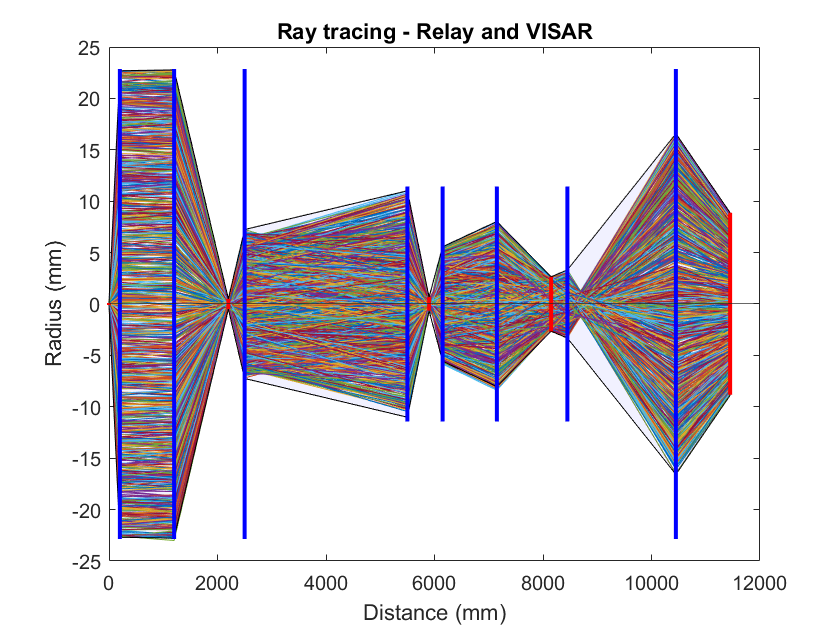

ImagePlanes = find(sum(abs(diff(TrackMag)))<0.01);
ImagePosition = PositionVISAR(ImagePlanes);

hold on
patch( [PositionVISAR,  fliplr(PositionVISAR)], [max(RayRadiiVISAR), -fliplr(max(RayRadiiVISAR))] , 'blue', 'FaceAlpha', 0.055)
for i = 1:length(ImagePlanes)
% ImageLocation = find(Position == i);
[ImageMagnitude, BiggestImageRay] = max((RayRadiiVISAR(:, find(PositionVISAR == i))));
line([ImagePosition(i) ImagePosition(i)], [min((RayRadiiVISAR(:, ImagePlanes(i)))) max((RayRadiiVISAR(:,ImagePlanes(i))))], 'color', 'r', 'LineWidth', 2);
end
hold off

% %Draw Lenses
% LensLocations = find(diff(PositionVISAR)==0);
% LensPositions = PositionVISAR(LensLocations)
% hold on
% for i = 1:length(LensPositions)
% line([LensPositions(i) LensPositions(i)], [-LensDiametersRelayAndVISAR(i)/2 LensDiametersRelayAndVISAR(i)/2], 'color', 'b', 'LineWidth', 2);
% end
% hold off
% title('Ray tracing')

%Draw Components. Can identify components because position doesn't change
%(i.e. not free space). Can identify lenses specifically because ray angle
%will change at that point. Use this to identify is a component is a lens -
%if it is, draw in a different color. %Lenses are blue, image plaes are
%red, and non-focussing components are black.
ComponentLocations = find(diff(PositionVISAR)==0);
LensLocations = find(abs(sum(diff(RayAnglesVISAR.').'))>0);
[LensLocations, IsComponentLens] = intersect(ComponentLocations, LensLocations);
ComponentPositions = PositionVISAR(ComponentLocations);
hold on
for i = 1:length(ComponentPositions)
    if ismember(i, IsComponentLens)
        line([ComponentPositions(i) ComponentPositions(i)], [-LensDiametersRelayAndVISAR(i)/2 LensDiametersRelayAndVISAR(i)/2], 'color', 'b', 'LineWidth', 2);
    else
        line([ComponentPositions(i) ComponentPositions(i)], [-LensDiametersRelayAndVISAR(i)/2 LensDiametersRelayAndVISAR(i)/2], 'color', 'k', 'LineWidth', 2);
    end
end
hold off
title('Ray tracing - Relay and VISAR')

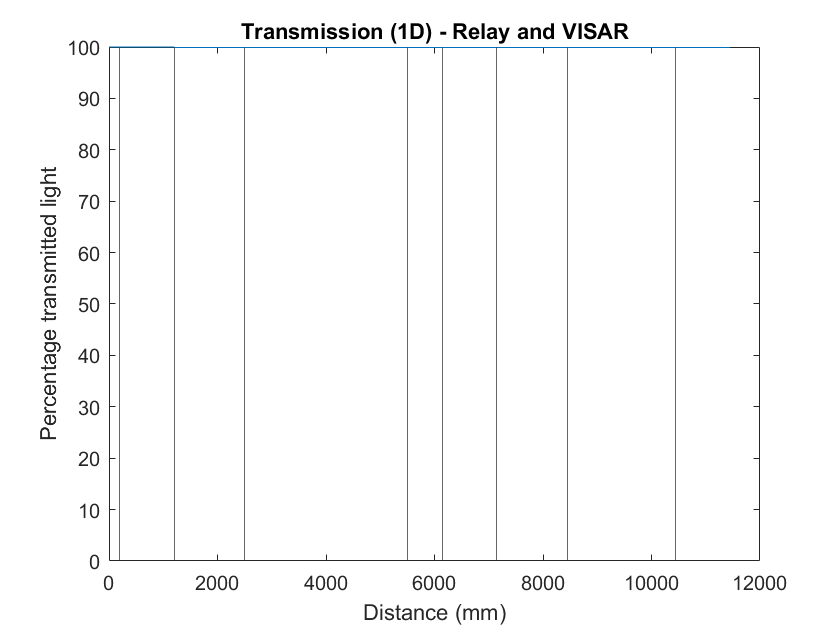


%RayLosses records a 1 if the ray is outside the lens diamter. Take a
%cumulative sum - any 0 value means the ray is still in the system at that
%point. Then use this to calculate fraction of rays still in the system.
SurvivingRays = cumsum(RayLossesVISAR,2)==0;
FractionalSurvivingRays = sum(SurvivingRays)./size(RayRadiiVISAR,1);

%Plot the fractional transmitted light
plot(PositionVISAR, FractionalSurvivingRays*100)
yline(0);
xlabel('Distance (mm)')
ylabel('Percentage transmitted light')
title('Transmission (1D) - Relay and VISAR')
for i = 1:length(ComponentPositions)
xline(ComponentPositions(i));
end



%Save the transmitted rays - those that make it to the end of the system.
TransmittedRays = RayRadiiVISAR./SurvivingRays(:, end);
TransmittedRays(any(isnan(TransmittedRays), 2), :) = [];
TransmittedRays(any(isinf(TransmittedRays), 2), :) = [];

% 
%  %Bin the ray radii to see where each ray is coming from. Binning can be
%  %awkward, as if the binning is wrong more point sources end up in one than
%  %the other. The way I defined it, this should be equal. So, we use integer
%  %binning (so that bin is centered on integer), and scale data so that each
%  %point sourece is on an integer, before scaling the bins back down so they
%  %work.
% [InputImageCounts,InputImageBinEdges] = histcounts(RayRadiiVISAR(:,1)/min(diff(unique(((RayRadiiVISAR(:,1)))))), 'BinMethod','integers');
% % histogram('BinEdges',InputImageBinEdges*min(diff(unique(((RayRadii(:,1)))))),'BinCounts',InputImageCounts)
% 
% %Idea output is all input rays make it to the end. We know the images of
% %the point source will be the original point sources times magnification,
% %so we can use this to scale the bins to integer and back.
% [IdealImageCounts,IdealImageBinEdges] = histcounts(RayRadiiVISAR(:,end)/(min(diff(unique(((RayRadiiVISAR(:,1))))))*abs(Magnification(end))), 'BinMethod','integers');
% histogram('BinEdges',IdealImageBinEdges*(min(diff(unique(((RayRadiiVISAR(:,1))))))*abs(Magnification(end))),'BinCounts',IdealImageCounts )
% 
% %And for real output. We use same bins as for above, to ensure correct
% %binning.
% [OutputImageCounts,OutputImageBinEdges] = histcounts(TransmittedRays(:,end)/(min(diff(unique(((RayRadiiVISAR(:,1))))))*abs(Magnification(end))), 'BinMethod','integers');
% hold on
% % histogram('BinEdges',OutputImageBinEdges*(min(diff(unique(((RayRadiiVISAR(:,1))))))*abs(Magnification(end))),'BinCounts',OutputImageCounts )
% histogram('BinEdges',OutputImageBinEdges,'BinCounts',OutputImageCounts )
% hold off
% title('Image  (1D) - Relay and VISAR')



%Calculate area of first lens, compared to area of sphere with r of first
%lens focal distance. This gives estimate of fraction of light that enters
%system. We actually use half sphere area, since we assume material behind
%object means the only available light for capture is that moving forward.
AreaOfLens = pi*((LensDiameters(1)/2)^2);
AreaOfHalfSphere = 4*pi*(FocalLength^2);
CapturedLight = AreaOfLens/AreaOfHalfSphere

CapturedLight = 0.0033

# Functions

function [OutputRayRadii, OutputRayRAngles, OutputRayLosses, Position] = FreeSpace(InputRayRadii, InputRayAngles, InputRayLosses,  Position, Distance)
DistanceOperator =  [1 Distance; 0 1];

%To build the input rays, take the last entry in each row - i.e., the most
%recent radius for each ray. Form a column vector with the equivalent
%angle. (Take most recent values, last column, flip to give a row, and then
%concatenate with the equivalent flipped column of angles)

InputRays = [InputRayRadii(:, end).'; InputRayAngles(:, end).'];

%For each input ray, calculate the output ray using the operator.
%Concatenate these as with the input rays.
OutputRays = [];
for i=1:size(InputRayRadii, 1)
CurrentOutputRay = DistanceOperator*InputRays(:,i);
OutputRays = [OutputRays CurrentOutputRay];
end

%Split back up into radii and angles, and append to the end of the input.
%Take the top row of the output rays (radii), flip to give a column, and
%append to the end of the input radii so the last column is the most recent
%radii for each ray.
OutputRayRadii = [InputRayRadii OutputRays(1,:).'];
OutputRayRAngles = [InputRayAngles OutputRays(2,:).'];

OutputRayLosses = [InputRayLosses, zeros(size(OutputRayRadii,1),1)];

%Save the current x position.
Position = [Position Position(end)+Distance];
end



%As for above - but a different operator (lens, rather than free space),
%and the position is not summed.

function [OutputRayRadii, OutputRayRAngles, OutputRayLosses, Position] = Lens(InputRayRadii, InputRayAngles, InputRayLosses,  Position, LensDiameter, FocalLength)
Lens = [1 0; -1/FocalLength 1];

InputRays = [InputRayRadii(:, end).'; InputRayAngles(:, end).'];
OutputRays = [];
for i=1:size(InputRayRadii, 1)
CurrentOutputRay = Lens*InputRays(:,i);
OutputRays = [OutputRays CurrentOutputRay];
end

OutputRayRadii = [InputRayRadii OutputRays(1,:).'];
OutputRayRAngles = [InputRayAngles OutputRays(2,:).'];

%Compare Radii of each ray to the lens diameter. If it's larger, the ray
%has left the system. Build an array which tracks when the ray has left the
%system.
RayRadiiOutsideLens = abs(OutputRayRadii(:,end))>LensDiameter/2;
OutputRayLosses = [InputRayLosses, RayRadiiOutsideLens];

Position = [Position Position(end)];
end

%Takes a list of radii and a list of angles, returns every possible combo
function [Radii, Angles] = AllCombos(RadiiValues, AngleValues)

Radii = repmat(RadiiValues, 1, length(AngleValues)).';
Angles = repelem(AngleValues, 1, length(RadiiValues)).';


end


%As for above, but for non-focusing components (i.e. mirrors, filters)
%where we need to check dimensions

function [OutputRayRadii, OutputRayRAngles, OutputRayLosses, Position] = NonFocussingComponent(InputRayRadii, InputRayAngles, InputRayLosses,  Position, LensDiameter)

%To build the input rays, take the last entry in each row - i.e., the most
%recent radius for each ray. Form a column vector with the equivalent
%angle. (Take most recent values, last column, flip to give a row, and then
%concatenate with the equivalent flipped column of angles)

InputRays = [InputRayRadii(:, end).'; InputRayAngles(:, end).'];

%As components does nothing to rays, input ray and output rays are equal
OutputRays = InputRays;

OutputRayRadii = [InputRayRadii OutputRays(1,:).'];
OutputRayRAngles = [InputRayAngles OutputRays(2,:).'];

%Compare Radii of each ray to the lens diameter. If it's larger, the ray
%has left the system. Build an array which tracks when the ray has left the
%system.
RayRadiiOutsideLens = abs(OutputRayRadii(:,end))>LensDiameter/2;
OutputRayLosses = [InputRayLosses, RayRadiiOutsideLens];

Position = [Position Position(end)];
end








%Given inputs of radii and angle values, for each point source calculates
%the rays that will reach the first lens (given the focal length and lens
%diameter). Then returns ray radii and angles in correct form, along with
%the capture angles for each ray.
function [Radii, Angles, CaptureAngles] = CaptureLight(RadiiValues, AngleValues, FocalLength, LensDiameter)

Radii = [];
Angles = [];
CaptureAngles =[];

for i = 1:length(RadiiValues)
    Angle1 = atan((LensDiameter/2 - RadiiValues(i))/FocalLength);
    Angle2 = atan((-LensDiameter/2 - RadiiValues(i))/FocalLength);
    TempAngleValues = AngleValues(AngleValues<max([Angle1 Angle2]));
    TempAngleValues = AngleValues(TempAngleValues>min([Angle1 Angle2]));
    Radii = [Radii; repmat(RadiiValues(i), length(TempAngleValues), 1)];
    Angles = [Angles; TempAngleValues.'];
    CaptureAngles = [CaptureAngles; Angle1 Angle2];
end    
    

end
    

%Capture light, but each ray is placed with a random position and angle.
function [Radii, Angles, CaptureAngles] = CaptureLightMC2(ObjectRadius, NumRays, FocalLength, LensDiameter)

Radii = [];
Angles = [];
CaptureAngles =[];

RadiiValues = (rand(1,NumRays)-0.5).*(ObjectRadius*2);

for i = 1:length(RadiiValues)
    
    Angle1 = atan((LensDiameter/2 - RadiiValues(i))/FocalLength);
    Angle2 = atan((-LensDiameter/2 - RadiiValues(i))/FocalLength);
    
    TempAngleValues = Angle2 + (Angle1-Angle2) .* rand(1,1);

    Radii = [Radii; repmat(RadiiValues(i), length(TempAngleValues), 1)];
    Angles = [Angles; TempAngleValues];
    CaptureAngles = [CaptureAngles; Angle1 Angle2];
end    
    

end




